# **Orbital Mechanics of a Human Cannon**

*Authors: *Drew Pang and Omar Salih

## Question:

**Prompts:**

- What is/are the motivating question(s)? 

- What type of question is this (explanatory, predictive, or design)?

- Why is this an important or interesting question?

- What will we learn by asking this question?

**Question: **What horizontal velocity from the Earth should a person be launched at to hit the moon? 

This is a design question because we are optimizing this model to answer our question. The unintuitive nature of orbital physics makes this question interesting to not only us, but astrophysicists, daredevils, and astronauts. Of course, we will have more assumptions to further narrow the scope of our model. We will learn about the intricacies of orbital mechanics, and how complex the process of launching things into orbit truly is. 

## **Model:**

**Prompts:**

- How are you going to answer your question? 

- What assumptions are you making? Are these good or bad assumptions?

- How did you develop and refine your model?

- What additional representations of your model help to communicate it to your reader (e.g., equations, stock and flow diagrams)? 

- How did you set the parameters of your model?

- How did you verify your model?

- Optional: If you had more time, what plan would you use to validate your model?

Schematic Diagram

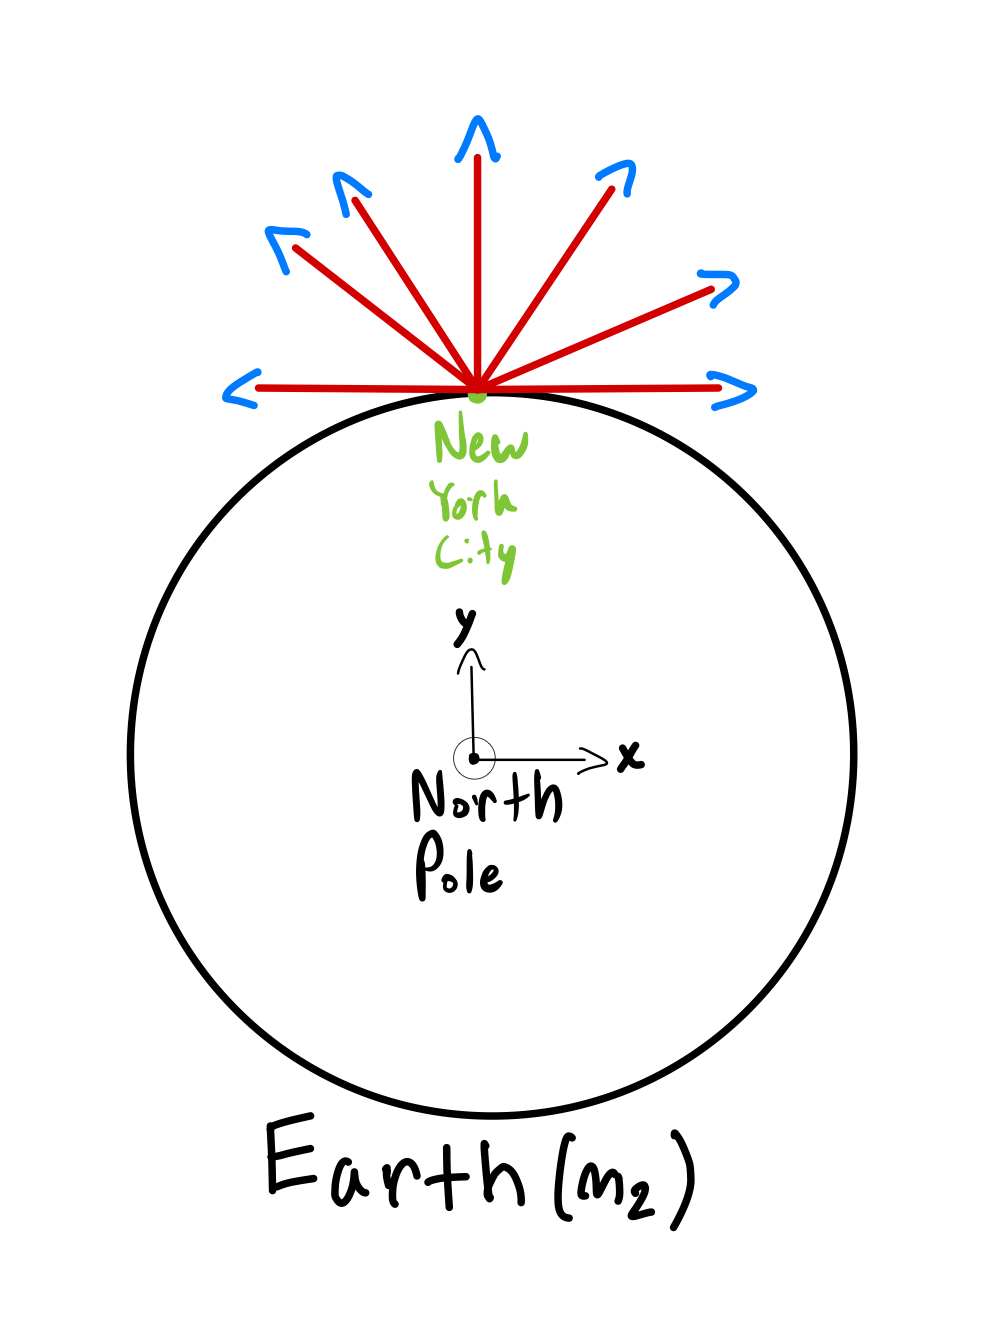

Free Body Diagram

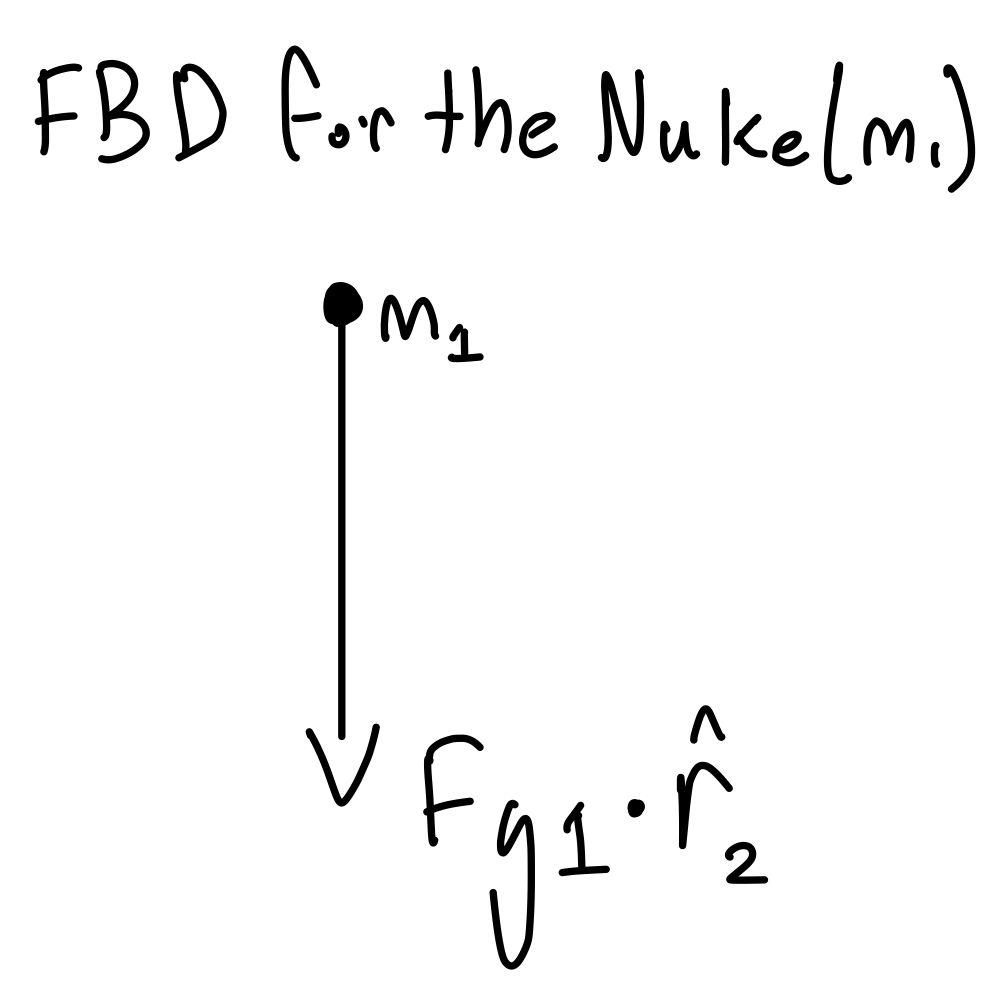

$m_1$ = Mass of the Nuke

$m_2
$ = Mass of the Earth

$F_{g1}$ = Force of Gravity of the Earth

Assumptions:

- The Earth and Moon are stationary

- The Earth has no atmosphere, and thus there is not air resistance acting on the human

- The Earth and Moon are perfect spheres


$$\frac{d^2p}{dt^2} = \frac{Gm_1}{r_{1}^2}\hat{r_1}+\frac{Gm_2}{r_{2}^2}\hat{r_2}\\
\frac{dv}{dt} = \frac{Gm_1}{r_{1}^2}\hat{r_1} + \frac{Gm_2}{r_{2}^2}\hat{r_2}\\
\frac{dp}{dt} = \hat{v}$$


earthVelocity = [11000,0]; % (m/s)

[T, M] = body_2D_ode45(earthVelocity);

clf;
hold on
plot(M(:,1), M(:,2));

% Plot Earth
points = linspace(0, 2*pi, 500);
r = 6.371e6;
x = r*cos(points);
y = r*sin(points);
plot(x,y)


% Plot Moon
points = linspace(0, 2*pi, 500);
r = 1.738e6;
x = r*cos(points) + 3.844e8;
y = r*sin(points);
plot(x,y)

xlabel('X Distance from Center of Earth');
ylabel('Y Distance from Center of Earth');
title('Body Orbit of Earth and Moon')

axis equal

## **Results:**

**Prompts:**

- What results did your model generate?

- Are there any key points of information in your results that  are most important or that will be most useful in your interpretation?  (Label key elements of your results figures.) 

## **Interpretation:** 

**Prompts:**

- How do the results answer the question?

- Do you think the answer is a good one? 

- What are the limitations of your model? 

- If you were going to continue developing your model, what next steps might you take? 

## Resources